# Non-uniform transmission line simulator

(select 'Hide code' mode)

The software provided here is a simulator for the time-domain response of Non-Uniform Transmission Lines with resistive load and real voltage source. 

Given the required input data, the software generates graphs illustrating the voltage and current behavior along the line.

Three types of waveform are available:

- Sine: with frequency $f_S$

- Step

- Rectangular pulse: only the first traversal is shown (intended to highlight signal distortion specifically)

## Enter the desired values in the input boxes

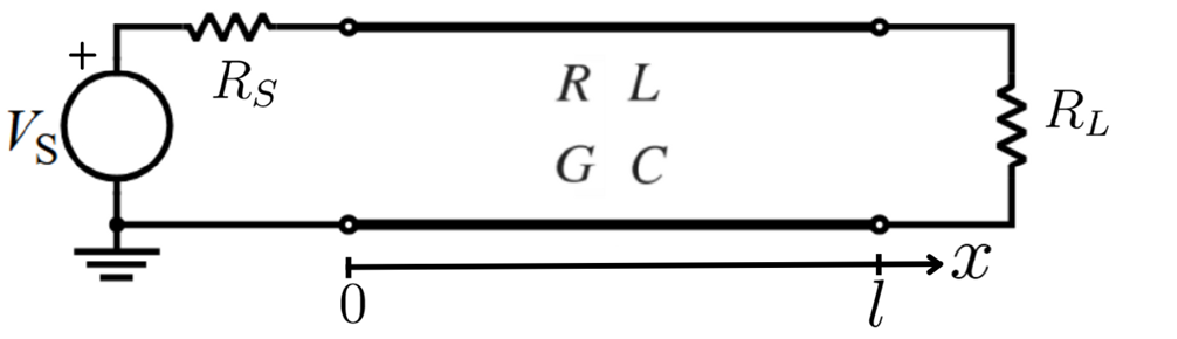

close all
clc
clear
clf reset
%--------------------------------------------------------------%
%-----------------------------input data-----------------------%
%--------------------------------------------------------------%


Numeric precision:

numeric_precision = "low";


Type of input wave form:

type_of_input = "pulse";


$$V_S \, [V] = \qquad \qquad \qquad \qquad R_S\, [\Omega] = \qquad \qquad \qquad \qquad f_S\,[Hz] =$$


V_S = 10;R_S = 0.5;f_S =  2.1e4;



$$R_L \, [\Omega] =$$


R_L = 2;


$$l \, [m] = $$


l = 100;


if numeric_precision == "low"
    n_cell = 3000;                              %number of elementary cells
    n_harm = 1000;                              %number of harmonics calculated (starting from the harmonic 0) 
    
elseif numeric_precision == "high"
    n_cell = 9000;                              %number of elementary cells
    n_harm = 3000;                              %number of harmonics calculated (starting from the harmonic 0) 
   
end


dx = l/(n_cell-1);                              %length of a single cell
x = linspace(0,l,n_cell);                       %space vector                        

Check the following box to insert a window of discontinuity along the line:

there_is_discontinuity = true;

Note: Alternatively, you may enter primary line constants as expressions of the vector 'x'.

Line parameters, nominal and at the window of discontinuity:


$$R\, \left[ \,\frac{\Omega}{m} \; \right] = \qquad \qquad \qquad \qquad   R_\text{window}\, \left[ \,\frac{\Omega}{m} \; \right] =$$


R = 1e-3;   R_window = 1e-2;
R = R + 0*x;                                  %to make sure that R is a vector



$$L\, \left[ \,\frac{H}{m} \; \right] = \qquad \qquad \qquad \qquad  L_\text{window}\, \left[ \,\frac{H}{m} \; \right] =$$


L = 1e-6;   L_window = 1e-5;                   
L = L + 0*x;                                  %to make sure that L is a vector



$$G\, \left[ \,\frac{S}{m} \; \right] = \qquad \qquad \qquad \qquad  G_\text{window}\, \left[ \,\frac{S}{m} \; \right] =$$


G = 1e-3;   G_window = 1e-4;                     
G = G + 0*x;                                 %to make sure that G is a vector



$$C\, \left[ \,\frac{F}{m} \; \right] = \qquad \qquad \qquad \qquad  C_\text{window}\, \left[ \,\frac{F}{m} \; \right] =$$


C = 1e-6;   C_window = 1e-7;   
C = C + 0*x;                                  %to make sure that C is a vector

Central position of the window [m] = 

window_position = 50;

Width of the window [m] = 

window_width = 20;

Type of discontinuity:

type_of_discontinuity = "abrupt";       %smooth: gassian-like    abrupt: piecewise function

Parameters for the animation illustrating voltage and current in the line over time:

Duration of the animation [s] = 

t_animation = 10;           %number of seconds for animated simulation (for Voltage/current throughout the line at different instants)
frame_rate = 15;                              %frames per second (for Voltage/current throughout the line at different instants) 


Number of times the wave reflects back and forth = 

n_bounces = 20;

Note: The simulation automatically stops once the transient is complete.

 

%--------------------------------------------------------------------------------------------%
%----------------------------------simulation------------------------------------------------%
%--------------------------------------------------------------------------------------------%


%------------------------adding the discontinuity to the line--------------------------------%
if there_is_discontinuity == 1
    if type_of_discontinuity == "smooth"
        R = R + (R_window - R).*exp(-((x - window_position)/(window_width/3)).^4);
        L = L + (L_window - L).*exp(-((x - window_position)/(window_width/3)).^4);
        G = G + (G_window - G).*exp(-((x - window_position)/(window_width/3)).^4);
        C = C + (C_window - C).*exp(-((x - window_position)/(window_width/3)).^4);

    elseif type_of_discontinuity == "abrupt"
        R = (R_window - R) .* (abs(x - window_position) < window_width/2)   +   R;
        L = (L_window - L) .* (abs(x - window_position) < window_width/2)   +   L;
        G = (G_window - G) .* (abs(x - window_position) < window_width/2)   +   G;
        C = (C_window - C) .* (abs(x - window_position) < window_width/2)   +   C;
    end
end




if type_of_input == "pulse"
    R_L = sqrt(L(end)/C(end));                      %since only the first traversal is shown, R_L is irrelevant for the simulation. Thus, for lightening computation we set R_L = Z_0
end

wave_travelling_time = l*mean(sqrt(L.*C));          %time necessary for the wave to traverse the entire line. In fact 1/mean(sqrt(L.*C)) = average wave speed

%-----------------------------------------------------------------------------------------------------------------%
%            In order to use the Discrete Fourier Transform, the signal is assumed to be periodic                 %
%                            In the following lines, the carrier frequency is calculated                          %
%-----------------------------------------------------------------------------------------------------------------%


%---------calculating n_min = number of bounces after which further reflections are negligible---------%

z_0_in = sqrt(L(1)/C(1));                         %Z_0 seen from the line's entrance 
z_0_out = sqrt(L(end)/C(end));                    %Z_0 seen from the line's end 

rho_S = (R_S - z_0_in)/(R_S + z_0_in);            %reflection coefficient at the source
rho_L = (R_L - z_0_out)/(R_L + z_0_out);          %reflection coefficient at the load


% Each reflection causes attenuation by rho_S (source) or rho_L (load)
% After n reflections: total attenuation = (rho_S * rho_L)^(n/2)

if abs(rho_S*rho_L) < 10^(-2*2/3)                 %n_min is at least 3
    n_min = 3;                            
elseif abs(rho_S*rho_L) > 10^(-2*2/30)            %if n_min is bigger than 30, simulation is not feasible
    errordlg("R_L and R_S are both either too big or too small compared with Z_0", "Unfeasible simulation");
    return;
else                                              %we set that the reflection is regligible when (rho_S*rho_L)^(n_bounces/2) < 0.01
    n_min = ceil(2*log(0.01)/log(abs(rho_S*rho_L)));
end



if type_of_input == "step"
    n_min = n_min + 1;                          % the last traversal will not be shown, because it is disturbed by the incoming falling edge

elseif type_of_input == "pulse"
    n_min = n_min;                              % the only traversal shown is not disturbed by the incoming falling edge, since n_min is at least 3

elseif type_of_input == "sine"
    N_periods = ceil(n_min*wave_travelling_time  *  f_S)  +  1  + 1;  %N_periods = number of sine cycles per half-period of the periodized signal 
                                                                      % " + 1" so that the last period is shown at transient over
                                                                      % " + 1" this period will be partially shown since the simulation is disturbed by the incoming falling edge%
    
    n_min = N_periods/f_S  /  wave_travelling_time;                   %n_min = Half-period duration of the periodized signal / time for single reflection
end


%-------------calculating f = carrier frequency------------------%

n_bounces = min(n_bounces, n_min - 1);              %The value of n_bounces is reduced to fit within the transient
                                                    %" -1" because the final traversal is not shown, since it is disturbed by the incoming falling edge%

t_len = max(t_animation*frame_rate, 200);           %number of points for numeric plotting (at least 200)


f = 1/(2*n_min*wave_travelling_time);               %frequency required to ensure that in the half-period the wave reflects n_min times

if type_of_input == "pulse"
    t_max = wave_travelling_time;                   %for the pulse we choose to shown only the first traversal
else
    t_max = n_bounces*wave_travelling_time;         %Time window displayed: [0, t_max], where t_max = time necessary for the wave to go back and forth at least n_bounces times
end


t = linspace(0, t_max, t_len);                      %Time vector


%----------------------------------------------calculating the harmonics of the input wave-------------------------------------------------------%

harm = (0:n_harm-1).';                          %vector with the hamonic numbers   NB: harm(n) = n-1
syms n


if type_of_input == "pulse"
    c(n) =  piecewise(n == 0, 1/(20*n_min), -i*(1-exp(-i*2*pi*n/(20*n_min)))/(2*n*pi));     %complex coefficient of the pulse wave's Fourier series. The pulse is not zero for T = wave_travelling_time/10

elseif type_of_input == "step"
    c(n) =  piecewise(n == 0, 1/2, -i*(1-exp(-i*pi*n))/(2*n*pi));                           %complex coefficient of the square wave's Fourier series

elseif type_of_input == "sine"
    c(n) =  piecewise(n == 0, 1/2, -i*(1-exp(-i*pi*n))/(2*n*pi));
    c(n) = 1/2*(c(n+2*N_periods) + c(n-2*N_periods));                                       %complex coefficient of the periodized sine wave

end

%the last formula is obtained as follows: 
%   our input: u(t)*cos(2 pi f_S t)
%   the Fourier coefficients of u(t): c(n),
%   the Fourier coefficientsof cos(2 pi f_S t):     1/2 if n = +- 1%
%                                                   0 else
%
%   the product in time domain becomes the convolution in frequency domain

a_n = 2*real(  double( c(harm) )  );        %coefficients of the cosines
a_n(1) = double(c(0));                      %DC component
b_n = 2*imag(  double( c(harm) )  );        %coefficients for the sines 

V_S_harm = V_S*(a_n + j*b_n);               %harmonic components as complex numbers 



%-----------------------------initializing main variables---------------------------------------%

z = zeros(n_harm,n_cell);
v_harm = zeros(n_harm,n_cell);
i_harm = zeros(n_harm,n_cell);
z_cell = (R + 2j*pi*harm*f*L)*dx;                   %z(harmonic, cell) = value of z for every cell and harmonic
y_cell = (G + 2j*pi*harm*f*C)*dx;                   %y(harmonic, cell) = value of y for every cell and harmonic

%--------------------------simulation for z(x) for every harmonic-------------------------------%


z(:,n_cell) = R_L;                                                      %the impedance seen from the line's end is simply R_L

for k = n_cell-1:-1:1 
    z(:,k) = z_cell(:, k) + z(:, k+1)./(1+z(:, k+1).*y_cell(:, k));     %we move from one cell to the previuos one. 
                                                                        % The input impedance is given by the series between: 
                                                                        %     Z_cell 
                                                                        %     the parallel between Y_cell and the input impedance seen from the next cell
end 

%------simulation for v(x), i(x) for every harmonic --> v(harmonic, cell) i(harmonic, cell)-----%


i_harm(:, 1) = V_S_harm./(R_S+z(:, 1));                                 %impedance seen by the generator = R_S + Z(0)  
v_harm(:, 1) = V_S_harm - R_S.*i_harm(:, 1);                            %voltage drop across R_S = R_S.*I(0) 
for k = 2:n_cell 
    v_harm(:, k) = v_harm(:, k-1) - z_cell(:, k-1).*i_harm(:, k-1);     %voltage drop across Z(x) = Z(x).*I(x)
    i_harm(:, k) = i_harm(:, k-1)./(1+z(:, k).*y_cell(:, k-1));         %current divider between z(x) and Y_cell
end 

%--------------------------------calculation of v(x,t) and i(x,t)-------------------------------%


%v_arr(t, cell) = v(t,x)    i_arr(t, cell) = i(t,x)

v_arr = v_harm(1,:);                          %the first harmonic is the DC component
i_arr = i_harm(1,:);                

%summing all harmonics
for k = 2:n_harm
    v_arr =  v_arr + abs(v_harm(k,:)).*cos((k-1)*2*pi*f*t.' + angle(v_harm(k,:)));
    i_arr =  i_arr + abs(i_harm(k,:)).*cos((k-1)*2*pi*f*t.' + angle(i_harm(k,:)));
end

v_max = max(v_arr, [], "all");                % range of y-values for setting the graph axis
v_min = min(v_arr, [], "all");
i_max = max(i_arr, [], "all");                
i_min = min(i_arr, [], "all"); 


# Graphs

#### Voltage and current throughout the line at different instants

Primary line constants are plotted with normalized values

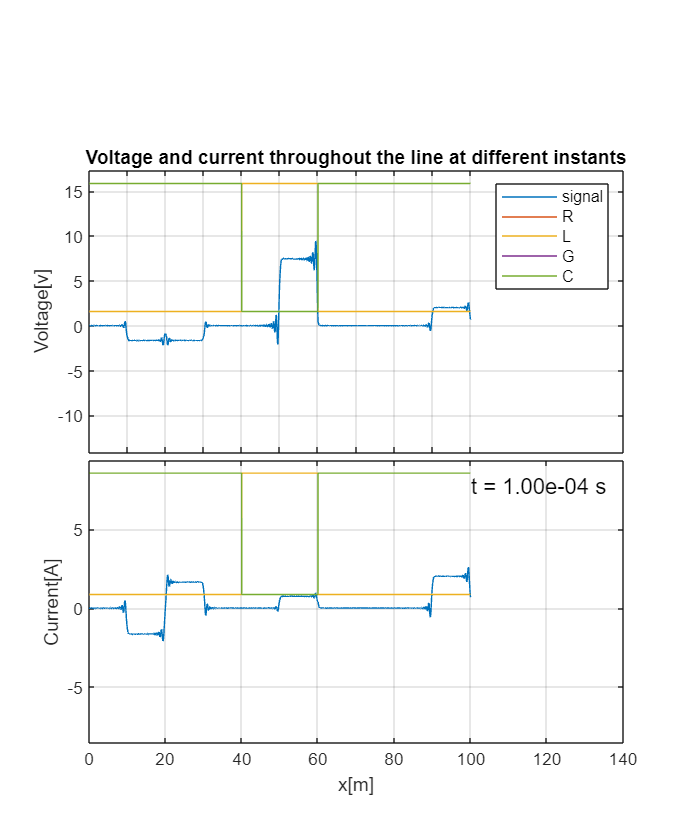


%---------------------------------------------------------------------------------------------------------%
%----------------------plotting voltage and current throughout the line at different instants-------------%
%---------------------------------------------------------------------------------------------------------%

figure('Position', [0,0,500,600]);                                      %new figure with fixed width and height

reduced_index = ceil(linspace(1, t_len, t_animation*frame_rate));       %not all instants need to be shown (only as much as the length of the animation times the frame rate)

%----------------------Voltage------------------------%

s1 = subplot(2,1,1);
s1.Position(2) = 0.452;                                                  %setting the position of the subplot
p_v = plot(0,0);

hold on 
plot(x,R/max(R)*v_max*1.1)
plot(x,L/max(L)*v_max*1.1)
plot(x,G/max(G)*v_max*1.1)
plot(x,C/max(C)*v_max*1.1)
hold off


p_v.XData =  x;
title("Voltage and current throughout the line at different instants")
xticklabels([]);                                        %to eliminate axis'numbers          
ylabel("Voltage[v]")
axis([0,l*1.4,  v_min*1.1 , v_max*1.2]);                %fixed rage for the axis
grid on;


legend('signal', 'R', 'L', 'G', 'C')


%---------------------Current-------------------------%

s2 = subplot(2,1,2);
s2.Position(2) = 0.1;                                   %setting the position of the subplot
p_i = plot(0,0);

hold on 
plot(x,R/max(R)*i_max*1.1)
plot(x,L/max(L)*i_max*1.1)
plot(x,G/max(G)*i_max*1.1)
plot(x,C/max(C)*i_max*1.1)
hold off


p_i.XData =  x;
xlabel("x[m]");
ylabel("Current[A]")
axis([0,l*1.4,   i_min*1.1, i_max*1.2]);                %fixed rage for the axis
grid on;

%----------------generating all frames----------------%

for k = reduced_index
    p_v.YData = v_arr(k,:);
    p_i.YData = i_arr(k,:);
    txt = text(l, i_max, "t = "+num2str(t(k), "%.2e")+" s", "FontSize", 12);    %text indicating time's value
    pause(1/frame_rate)
    %delete text for the new one, exept the last one
    if k ~= t_len
       delete(txt);
    end
end

#### Voltage and current over time at different sections

Use the cursor to select the x position along the line

x = 0 corresponds to the line entrance

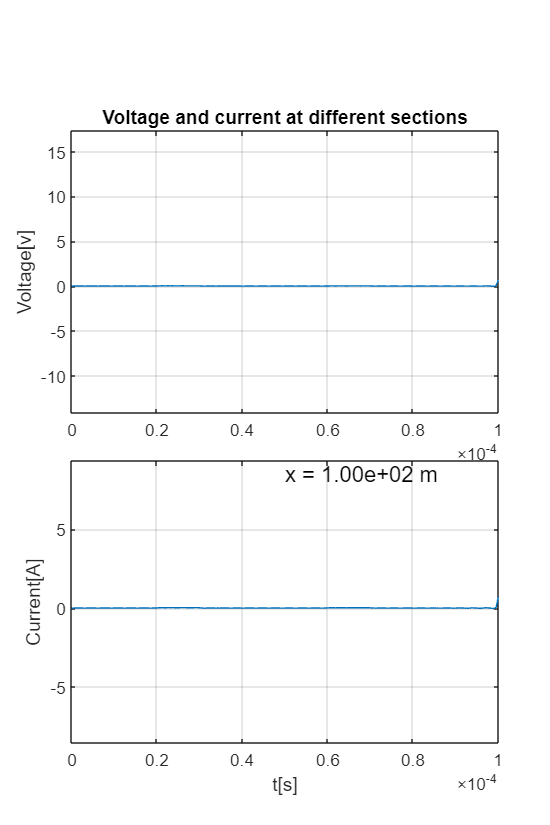

%---------------------------------------------------------------------------------------%
%-------------------------plotting the signal at different sections---------------------%
%---------------------------------------------------------------------------------------%


figure('Position', [0,0,400,600]);              %new figure with fixed width and height

n_step = 20;                                    %number of steps for the slider

%---------------------voltage---------------------%


s1 = subplot(2,1,1);
s1.Position(2) = 0.5;                           %setting the position of the subplot
p_v = plot(0,0);
title("Voltage and current at different sections")
ylabel("Voltage[v]")
grid on

p_v.XData = t;                                  % time is on the X axis                                    

axis([0, t_max,    v_min*1.1, v_max*1.2]);      %fixed rage for the axis

%-------------------current----------------------%


s2 = subplot(2,1,2);
s2.Position(2) = 0.1;                           %setting the position of the subplot
p_i = plot(0,0);
xlabel("t[s]")
ylabel("Current[A]")
grid on

p_i.XData = t;                                  % time is on the X axis 

axis([0, t_max,    i_min*1.1, i_max*1.2]);      %fixed rage for the axis

%--------refreshing plot for assigned value------%


cursor_step = l/n_step;                         %step value for the slider

position =100;            %slider for choosing the position along the line

index = ceil((n_cell-1)*position/l) + 1;        %converting position to index

p_v.YData = v_arr(:,index);
p_i.YData = i_arr(:,index);

txt = text(t_max*0.5, i_max*1.1, "x = "+num2str(x(index), "%.2e")+" m", "FontSize", 12);  %text indicating the x position